## Universidade Federal de Alagoas

Processamento Digital de Sinais

## Nilson Sales de Carvalho

# Exemplo Seção 5.1.2

## Ilustração dos Efeitos de Atraso e Atenuação de Grupo

Iremos implementar o sinal mostrado abaixo, no domínio do tempo, que será usado como entrada do nosso sistema:

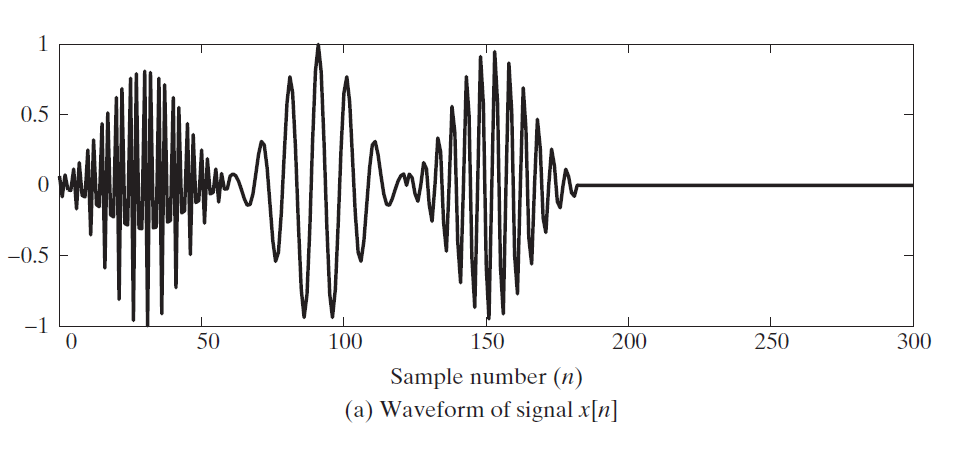

Este sinal, *x[n]*, é constituido da soma de três senoides:

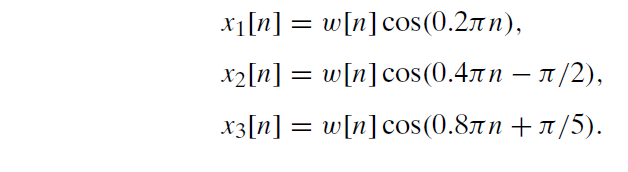

Onde a função *w[n],* que envolve cada senoide, é definida como sendo um pulso finito, de 61 pontos, da seguinte forma:

             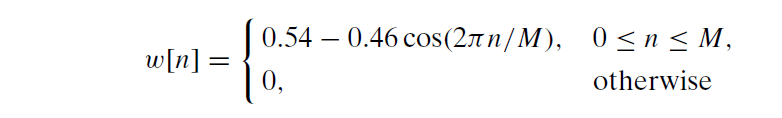

Com M = 60. A entrada total é, então, definida como:

  

A implementação do sinal em MATLAB ficou da seguinte forma:

M = 60;
n_samples = 300;
n = 1:n_samples;
w = zeros(1, n_samples); % envoltória

for N = 1:M
    w(N) = 0.54 - (0.46 .* cos(2*pi*N/M));
end

x1 = w .* cos(0.2*pi*n);
x2 = w .* cos(0.4*pi*n - pi/2);
x3 = w .* cos(0.8*pi*n + pi/5);

x = zeros(1, n_samples);

for N = 1:n_samples  % new_signal
    if (N-M-1 > 0) && (N-2*M-2 > 0)
        x(N) = x3(N) + x1(N - M - 1) + x2(N - 2*M - 2);
    elseif (N-M-1 > 0)
        x(N) = x3(N) + x1(N - M - 1);
    elseif (N-2*M-2 > 0)
        x(N) = x3(N) + x2(N - 2*M - 2);
    else
        x(N) = x3(N);
    end
end

Obtendo ainda a Tranformada de Fourier do sinal, temos:

X = fft(x);
Y = fftshift(X);

figure(1), clf
subplot(1,2,1)
plot(x)
grid

subplot(1,2,2)
plot(abs(Y))
xticks([30, 90, 150, 210, 270])
xticklabels({'-0.8\pi','-0.4\pi','0','0.4\pi','0.8\pi'})
grid

O que nos dá o sinal no tempo e na frequência que queríamos:

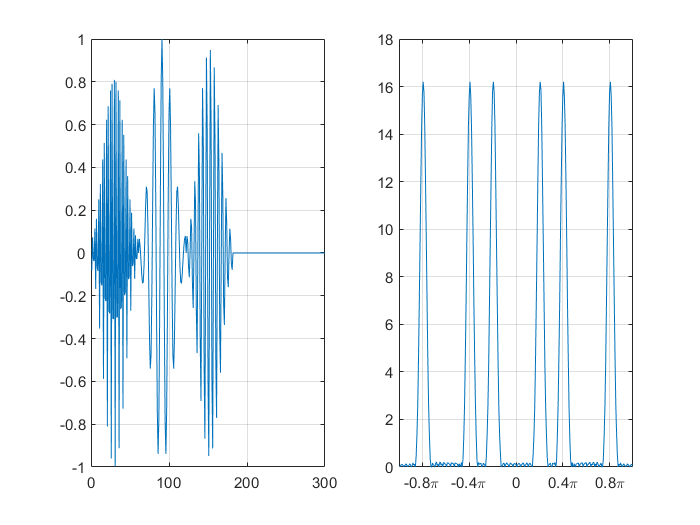

Precisamos agora implementar nosso sistema, que é definido da seguinte forma:

           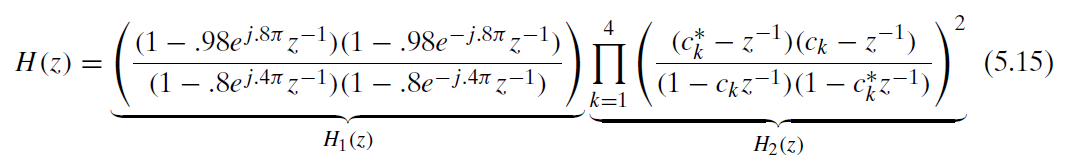

Com *ck = 0.95*e^j(.15π+.02πk)* e *k = 1, 2, 3, 4*. 

O sistema tem os seguintes polos e zeros:

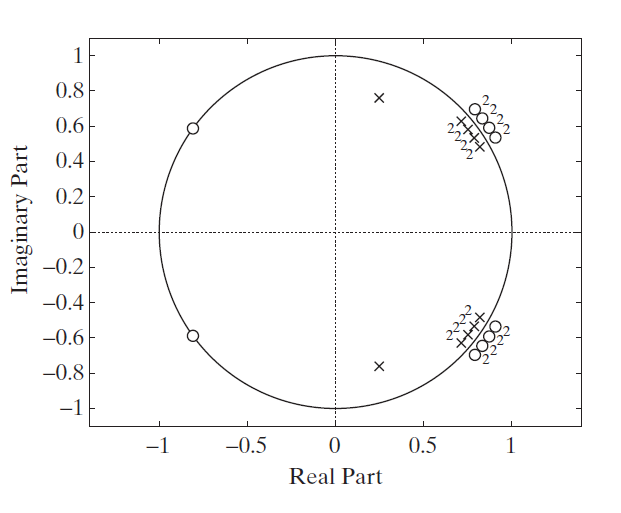

Observando o diagrama de Bode desse sistema, vemos algumas propriedades que serão aplicadas quando passarmos o nosso sinal por ele. Por exemplo, nas frequências 0.2π e 0.4π, haverá um ganho de amplitude, enquanto em 0.8π, o sinal será quase totalmente atenuado. Haverá ainda um grande atraso na frequência de 0.2π, e um pequeno atraso em 0.4π.

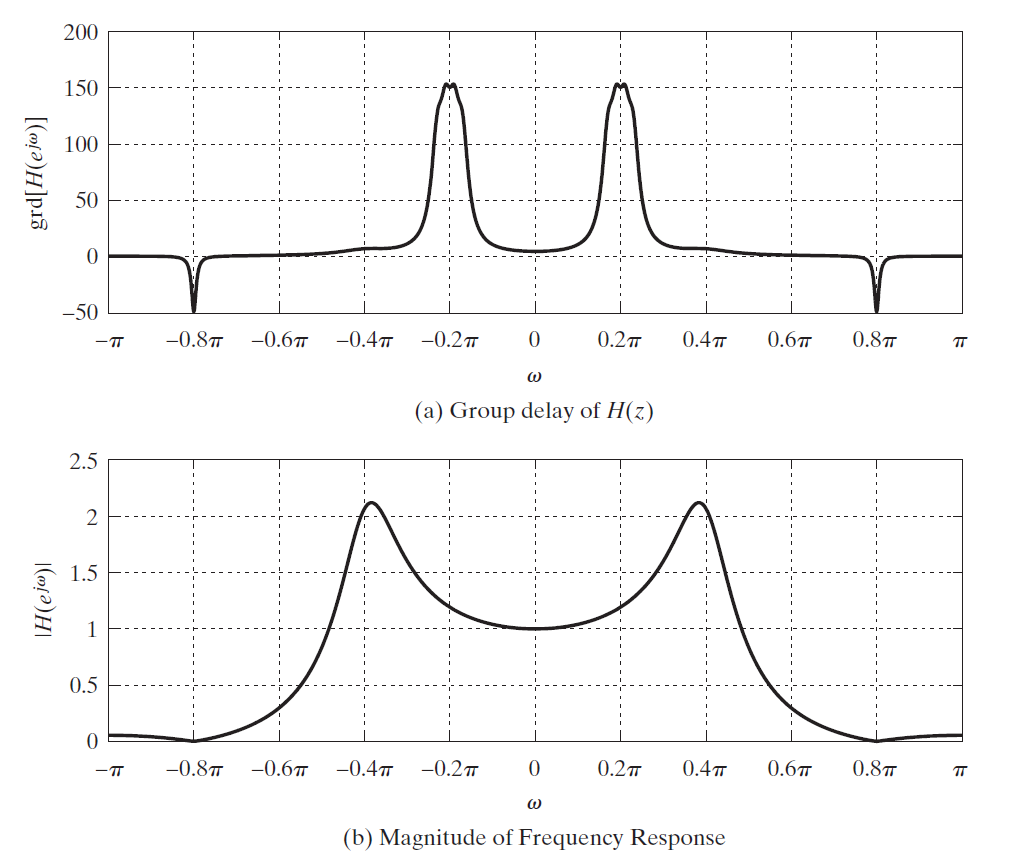

Para implementar o sistema desejado devemos criar uma função de transferência. Faremos isso atribuindo a **z** a nossa função de transferência e depois utulizando essa variável na nossa equação:

z = tf('z', -1);

H1 = ((1 - 0.98*exp(1j*0.8*pi)*z^(-1))*(1 - 0.98*exp(-1j*0.8*pi)*z^(-1))) / ((1 - 0.8*exp(1j*0.4*pi)*z^(-1))*(1 - 0.8*exp(-1j*0.4*pi)*z^(-1)));

H2 = 1;
for k = 1:4
    ck = 0.95*exp(1j*(0.15*pi+.02*pi*k));
    
    H2 = H2 * ( ((conj(ck) - z^(-1))*(ck - z^(-1))) / ((1 - ck*z^(-1))*(1 - conj(ck)*z^(-1))) )^2;
end

H = H1 * H2;

figure(2)
pzmap(H)

Ao observar o plano-Z do nosso sistema, vemos que está de acordo com o sistema pretendido:

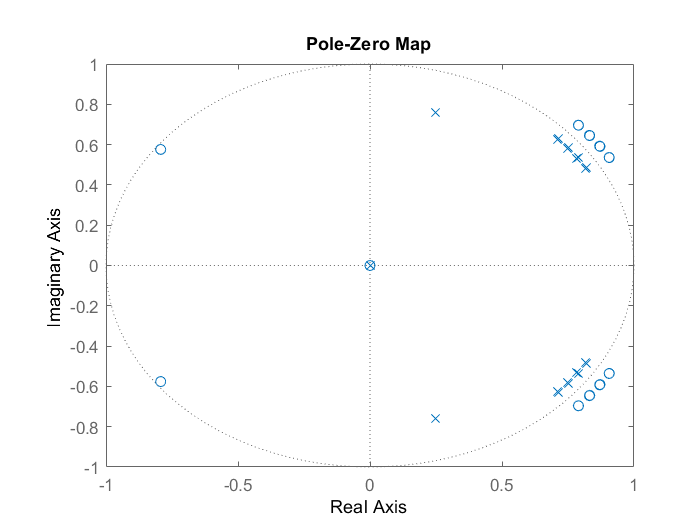

Agora que temos nosso filtro, vamos extrair seus coeficientes para utulizá-lo com a função filter() do Matlab. Em seguida utilizaremos os coeficientes para filtrar nosso sinal de entrada e plotar o resultado obtido:

[num,den] = tfdata(H,'v')
lot(filter(num, den, x))

O resultado obtido é exatamente o que esperávamos:

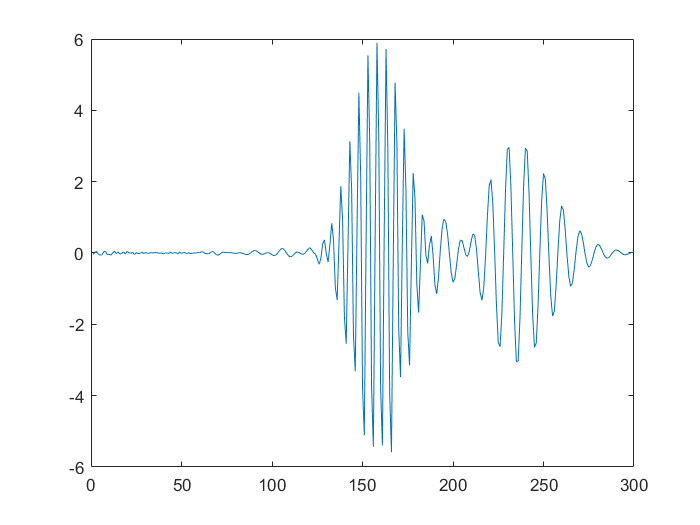

O pulso na frequência ω = 0.8π foi eliminado. Os outros dois pulsos tiveram sua amplitude incrementada e foram atrasados; o pulso em ω = 0.2π está ligeiramente mais largo e atrasado em 150 amostras, e o pulso em ω = 0.4π tem o dobro de amplitude e está atrasado em cerca de 10 amostras.